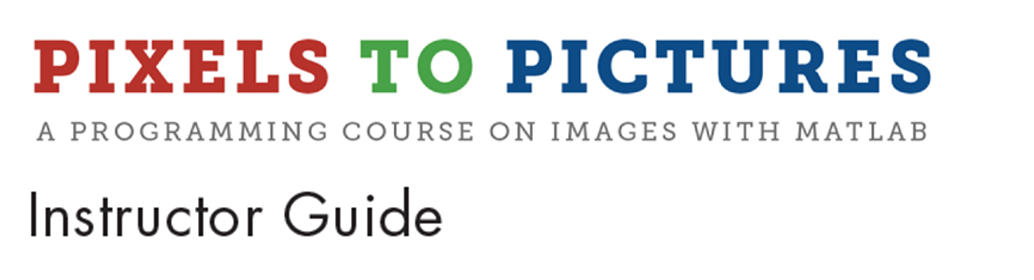

# Module 6: Functions and Operating on Images 

**Prerequisite Domain Knowledge:** Basic MATLAB syntax, indexing

**Expected Completion Time: **60 minutes

## Import and Visualize Images in MATLAB 

*Expected Duration: 30 minutes*

### Learning Objectives

- Execute functions

- Input and output arguments of function

- Import images into MATLAB

- Visualize imported images in MATLAB

- Learn about different image types

### Materials

- MATLAB®

- Worksheet "Understanding Functions"

- Worksheet "Reading Images Into MATLAB"

### **Steps**

Tell the students that we have learned a lot about images and colors. It is now time to actually bring an image into MATLAB and look at its characteristics.

We want to *read* in an *image* into MATLAB. To do that we need to use a function.

Distribute the **Understanding Functions Worksheet **to the students and explain to them that we will be spending a little time understanding functions. 

 
web('worksheets_and_handouts/UnderstandingFunctions.pdf', '-browser');

Have the students open the Live Script for this section by using the command below:

 
open 'ImportandVisualize.mlx'

Ask them to concentrate on the top half of the worksheet which has three columns of images. The first column is called ‘Input’, the second column, ‘Function’, and the third column, ‘Output’.

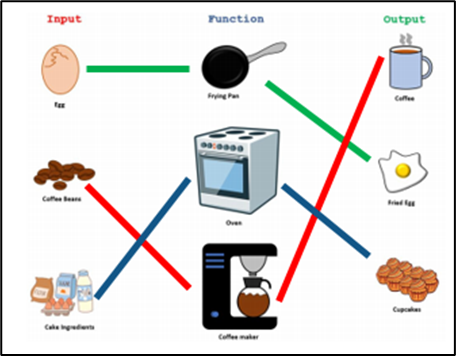

Observe that all the images are real life items, specially the ‘Function’ column shows appliances that have specific *functions* in the real world.

Their task is to match an appropriate input to each appliance and then to match them to the corresponding output. For example, the egg is an input to the skillet which gives a fried egg as output. 

Explain to them that in the real world there are appliances that perform specific functions. Similarly, in the programming world, commands that carry out specific functions are simply called ‘functions’.

Ask the students to keep their worksheets aside for now (we’ll return to the bottom half in the next section) and explain that a function in programming is a command that takes an input (e.g. egg), does something to the input (e.g. fries it) and, if needed, provides an output (e.g. fried egg). It has three parts with the following syntax:

- `<function name>` - name of the function you want to execute

- `<input>` - this is what the function will be executed on. 

- `<output variable>`- this is where the result of the execution is stored.

As an example, in MATLAB type:

Here, we are trying to find the square root of 9. The function name is `sqrt`. The input is 9 (the number we want to find the square root of) and the result is stored in the output variable `x`. 

Another example is

Here, the function `max`, will take the vector`[4 2 9]` as input and return the maximum value in that vector (9) stored in the output variable `s`.

MATLAB has many ready-to-use functions such as `sqrt `and` max`. Tell the students that they will be using several functions during the course. The point to remember is that each function has a specific *function*just like the appliances.

So now that we understand what a function is and what its purpose is, let’s use a function called `imread` to read an image into MATLAB. The function `imread` stands for “image read”.

Type out the following command 

Here, `imread` is reading in the image ‘bigben.jpg’ into MATLAB from the computer and storing it in a variable called `Image`.

Before pressing enter on the above command, point out a couple of things to the students:

- ‘bigben.jpg’ is a character array like the ones we created and hence the color is magenta.

- JPG is a file format that the computer uses to know that it is a digital image file. The computer uses different file formats for different applications. For example

- Documents -                      .DOC, .DOCX, .PDF, .TXT

- Music/Video Files -               .MP3, .MP4, .WAV, .AVI, .MOV

- Digital Images -               .JPG, .PNG, .TIFF, .BMP, .GIF

            (For images, .JPG and .PNG are the most popular.)

When you press enter, you will notice a lot of numbers flood the command window. Ask:

- * How they can avoid this flood of numbers in the command window? *

-     Hopefully they remember the semi-colon. 

- *What do you think all of these numbers are (represent)?  *

-     So when executed the command outputs all the RGB values of each pixel in the image to the command window.

Type the commands below to clean the slate by clearing out the existing variables in the Workspace and the commands in the Command Window:

Read in the input image one more time

This will create the variable in the Workspace but suppress the output in the Command Window.

Ask them to look at the **Workspace** and verify that they can see a variable called `Image `in there.

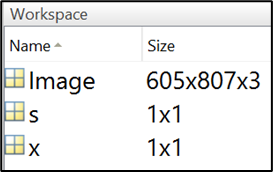     

Ask them if they remember what the size is showing. Remind them about the 3-D array discussion. The variable `Image` has the following characteristics:

- 605 * 807 = 488,235 pixels (half a million!)

- 605 rows

- 807 columns 

- 3 pages (Red, Green and Blue values for each pixel)

Now that we have the image in MATLAB, we would like to view the image to verify it has read in the correct one. To do this we will call another function called `imshow` which stands for “image show”.

Notice, this function does not give an output variable, because it doesn’t need to. Its purpose is to show the image.

Distribute the **Reading Images into MATLAB Worksheet **among the students. This activity lets them practice reading images into MATLAB, understanding their dimensions (rows, cols) and visualizing them. 

 
web('worksheets_and_handouts/ReadingImagesIntoMATLAB.pdf', '-browser');

Let the students know there is a folder called **Image Library **which contains many images. Ask them to look through the images and read in a few of them and view the images by using the `imread `and` imshow `functions.

Example:

Ask them to make a note of how many pixels, rows and columns each image has in the worksheet provided. 

***Note to teacher:**** Students might multiply the ***rows * columns * 3*** to find the total number of pixels in an image. They should not multiply by 3 as that just represents the 3 colors in each pixel.*

After about 10 minutes, gather the students to share what they read about the images.  Ask:

- **What surprising things did you uncover while reading images?  **

-     Encourage students to discuss if the number of pixels, rows, and/or columns within an image surprised them.

## Performing Basic Operations on Images 

*Expected Duration: 30 minutes*

### Learning Objectives

- Execute functions to perform basic operations on images.

- Modify a MATLAB script

### Materials

- MATLAB®

- Handout "MATLAB Functions"

### **Steps**

Now that we know how to read images into MATLAB and view them, we can start learning how to manipulate the images in MATLAB.  Let’s start first by learning how to perform basic operations on them such as flipping (mirroring), rotating, and resizing. Ask:

- *What kind of tools might an artist want to use if he or she wants to create a new painting?  *

-     Students may mention painting canvas, several painting brushes of varying shapes and sizes, painting palette, different water colors, etc.

- *Would it be possible for the artist to paint without these tools?  *

-     No. So we need to have all the necessary tools before we can start working on something.

Explain to the students that we can’t start creating our artwork in this class till we have all the right tools in our belt. In this section we will become familiar with the several different functions that we can apply on images -  or in other words -  we will start collecting the tools we might need to create our artwork.

Have the students open the Live Script for this section by using the command below:

 
open 'Basic_Ops_Images.mlx'

Explain that a script allows users to write multiple lines of code.

When the script opens up, have them run the first section of the script.

Explain to students that the "%" symbol indicates that the line of code is a "comment" and not something to be executed. MATLAB also turns the text green for ease.

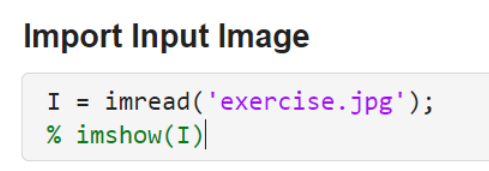

You can remove the comment by deleting the % symbol, and this turns the comment back into code:

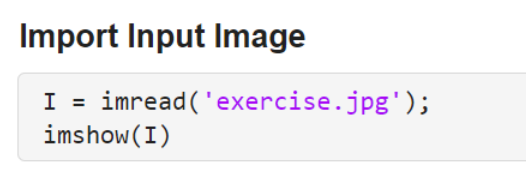

Click on the **Run Section** button in the Editor strip. This will individually run the section you are working in:

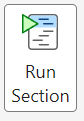

When you run a script, it executes all the lines of commands **sequentially**. It is a step up from the Command Window where you can run only one command at a time. 

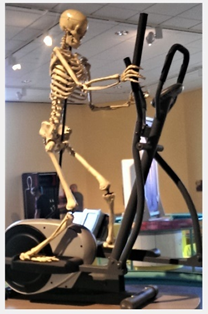

Distribute the **MATLAB Functions** **Handout** to the students and direct their attention to the Basic Operations sections. It has a list of functions we will be using in this section.

 
web('worksheets_and_handouts/MATLABFunctions.pdf', '-browser');

Start adding to the script by typing:

This function `flip` flips the input image `I` upside down and stores the result in the output variable `updown`.

To view the original image and the flipped image side by side we can use the `imshowpair` function as follows

- `figure`

-     This command creates a new figure window. Without this command, any new images will be overwritten in the previous figure window.

- `imshowpair(I,updown,``'montage')`

-     Click on Run again. The montage input tells MATLAB that we would like the images placed next to each other. The default option overlays the two images in different color bands. 

 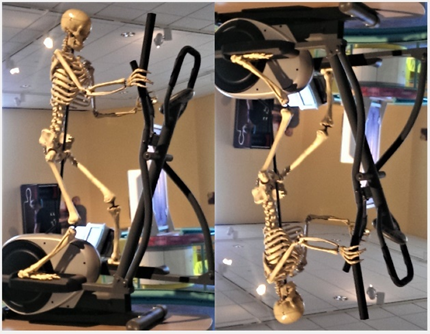

Another function `fliplr`, flips the input image left to right (lr) – mirror image. Add the following lines to the script and click on **Run Section**

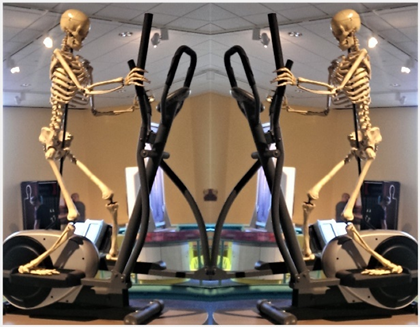

Remind the students that if they just want to see the output image on its own, they need to use `imshow`. Example:

We can also rotate the input image by using the `imrotate` function which takes two inputs. The first input is the image we would like to rotate and the second input is the angle we want to rotate it by. 

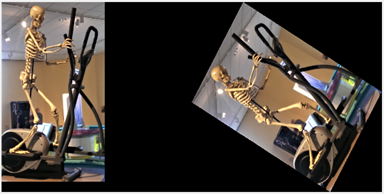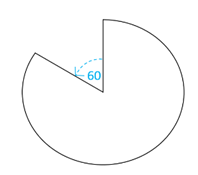

Ask the students to change the angle of rotation to 90 and rerun the code.

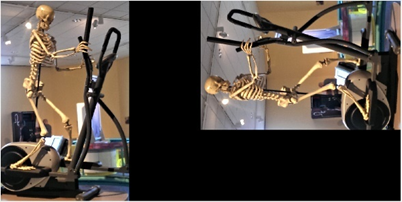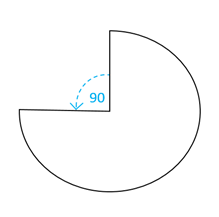

Next, we can resize the image in one of two ways

- Providing a scaling factor

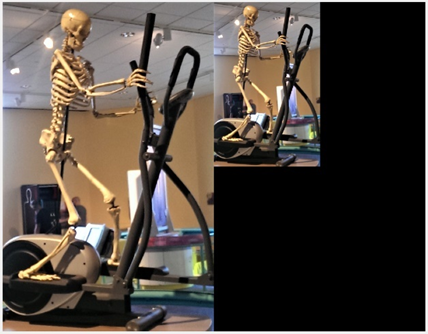

- When used in this manner, the `imresize` function scales the image to half its original size. Here the second input to the function is the scaling factor. **Run** the script and ask the students to verify that the number of rows and columns in `small` is indeed half that of the original image `I `in the Workspace.

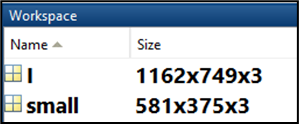

- Providing a fixed row and column value

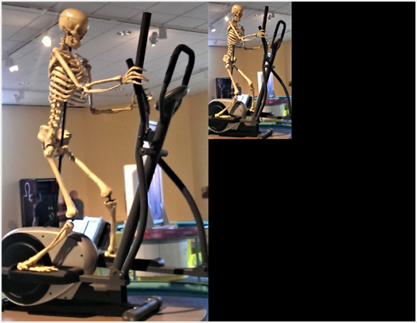

Here, the second input to `imresize` is a row vector that specifies the number of rows and columns we would like to resize the original image `I` to. In this example, it sets the number of rows in `small` to 500 and the number of columns to 300. Ask the students to verify this in the Workspace as well after running the script.

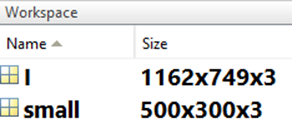

We can also snip out a region of interest from a larger image by using the `imsnip` function.

This opens the original image `I` and changes the mouse pointer to a plus sign. We can then select a region of interest with that. The region of interest is then stored in the variable `roi`.

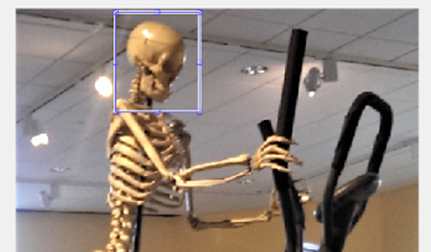

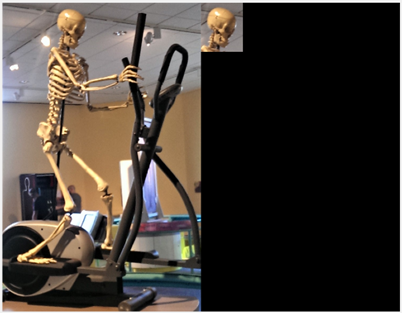

Congratulate the students on writing their first program in MATLAB. As they can see a program is simply a collection of several lines of commands that the computer understands and executes them line by line. 

Ask the students to bring back the **Understanding Functions Worksheet **and complete the second half based on what they just learnt. 

© COPYRIGHT 2024 by The MathWorks®, Inc.